# Canard Roll Control Model

### Overview

This script will serve as the primary model for the controls simulation. It will feature a cascaded PID control, with the PID values being gain scheduled based on a function of velocity V.

### State Values

Vx = Velocity in the X direction (Up) (m/s)

p = roll rate (deg/s)

x = altitude (m)

ix = moment of intertia about the x axis (kg/m^2)

m = mass (kg)

phi = current roll heading (deg)

dt = time step value

### Controller Values

Kp_P = Primary Proportinal coefficient as functino of Vx

Ki_P = Primary Integral coefficient as function of Vx

Kd_P = Primary derivative coefficient as function of Vx

Kp_S = Secondary proportional coefficient (not function of V)

Ki_S = Secondary integral coefficient (not function of V)

Kd_S = Seconday derivative coefficient ( not function of V)

### Control Values

can_theta = current angle of the canards (deg)

can_wmax = fastest control angular speed of canard (deg/s)

can_M = Moment created by canard (function of can_theta, Vx, and x)

- should make a helper function for this

alpha = can_M / I = angular acceleration (deg/s^2)

# Simulation Theory

If our goal is to control the Roll of the rocket, we need to consider in our simulation that we cannot simply read the heading of the rocket from our sensors. To compensate for this our control loop will need to manually integrate the roll rate to gain the heading. we should initially just try and controll roll rate before moving onto an alogorithim that can control the heading.

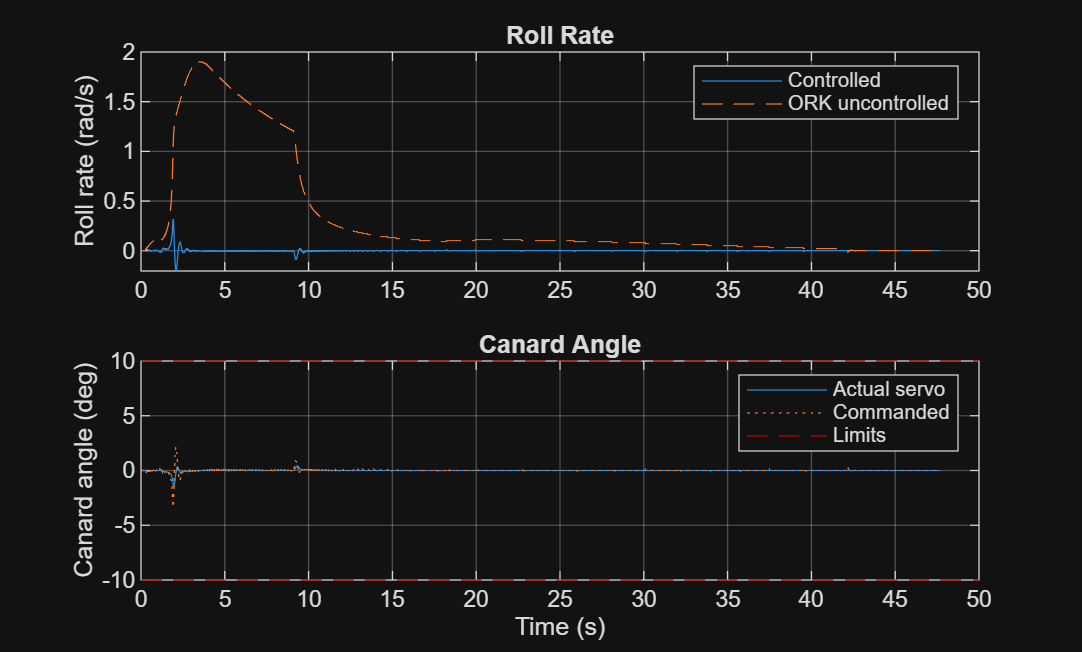

% |----- Inputs setup -----|
%[ork_filename, pathname] = uigetfile({'*.csv'});
%orkFullFile = fullfile(pathname, ork_filename);

%if isequal(ork_filename, 0)
%    error('No ORK simulation file was selected.');
%end

ork_data = readtable('Sim-Data.csv', VariableNamingRule="preserve");    %| Import data from an ORK sim csv

orkTime = ork_data.("# Time (s)");
x_ork = ork_data.("Altitude (m)");
Vx_ork = ork_data.("Vertical velocity (m/s)");
Ix_ork = ork_data.("Rotational moment of inertia (kg·m²)");
thrust_ork = ork_data.("Thrust (N)");
m_ork = ork_data.("Mass (kg)");
p_ork = ork_data.("Roll rate (r/s)"); %| This is a refernce array, once the controls loop starts it will not be used
p_ork = fillmissing(p_ork, 'constant', 0);
phi_ork = cumtrapz(orkTime, p_ork);   %| This too


%| Time interpolation and Timing variables

[orkTimeU, ia] = unique(orkTime,'stable');

t_step = 1e-3;
t = 0:t_step:orkTime(end);
x = interp1(orkTimeU, x_ork(ia), t);
Vx = interp1(orkTimeU, Vx_ork(ia), t);
Ix = interp1(orkTimeU, Ix_ork(ia), t);
thrust = interp1(orkTimeU, thrust_ork(ia), t);
m = interp1(orkTimeU, m_ork(ia), t);
p = interp1(orkTimeU, p_ork(ia), t);
phi = interp1(orkTimeU, phi_ork(ia), t);
a_dist = gradient(p, t);


% |------ CONTROLLER VALUES ------ |

Kp_P = 10;  %|------------------------
Ki_P = 0.5; %| Primary Loop PID values
Kd_P = 0.1; %|------------------------

Kp_S = 5;  %|------------------------
Ki_S = 0.5; %| Secondary Loop PID Values
Kd_S = 0.1; %|------------------------

p_target = 0;

% |------ System Dynamics Inputs ------ |

L = 3;           %| (N) Lift created by canards **UPDATE TO ARRAY ONCE CFD IS DONE
r = 0.2;      %| (m) moment arm/distance from canard CP to the body x axis**
can_theta = 0;   %| (deg) current canard angle
can_maxw = 1740; %| (deg/s) Max servo speed (change for test different servos)
can_maxt = 10;   %| (deg) Maximum allowed servo angle

% |------ MAIN LOOP ------|

ctrl_div = 20; %| Outer loop every 5 ms
p_ctrl = p;
can_cmd = 0;
can_theta_ctrl = zeros(n, 1);
n = numel(t);
u = zeros(n, 1); %| Control command history

phi_ctrl = zeros(1, n);  
phi_ctrl(1) = phi(1);   %| (rad) simulated roll angle
    
err_P_prev = 0;
err_S_prev = 0;
integ_P = 0;
integ_S = 0;

for k = 1:n-1
    dt = t(k+1) - t(k);

    % | Primary Loop Stuff (roll rate)
    if mod(k, ctrl_div) == 0   
        dt_c = ctrl_div*dt;
        err_P = p_target - p_ctrl(k);
        integ_P = integ_P + err_P*dt_c;
        deriv_P = (err_P-err_P_prev)/dt_c;
        err_P_prev = err_P;
        can_cmd = Kp_P*err_P + Ki_P*integ_P + Kd_P*deriv_P;
        can_cmd = max(min(can_cmd, can_maxt), -can_maxt);
    end
    u(k) = can_cmd;
    
    % | Secondary Loop (servo angle)
    err_S   = can_cmd - can_theta_ctrl(k);
    integ_S = integ_S + err_S*dt;
    deriv_S = (err_S - err_S_prev)/dt;   err_S_prev = err_S;
    can_w   = Kp_S*err_S + Ki_S*integ_S + Kd_S*deriv_S;   %| (deg/s)
    can_w   = max(min(can_w, can_maxw), -can_maxw);
    can_theta_ctrl(k+1) = can_theta_ctrl(k) + can_w*dt;
    
    % | Roll dynamics
    can_L = L * (can_theta_ctrl(k+1)/can_maxt);   %| (N) temp lift model
    can_M = 4*can_L*r;                            %| (N·m) canard roll moment
    M_dist = Ix(k)*a_dist(k);                     %| (N·m) ORK disturbance
    p_dot = (can_M + M_dist) / Ix(k);             %| (rad/s²) roll accel
    p_ctrl(k+1) = p_ctrl(k) + p_dot*dt;        %| (rad/s) new roll rate
    phi_ctrl(k+1) = phi_ctrl(k) + 0.5*(p_ctrl(k) + p_ctrl(k+1))*dt;   %| trapezoid
end

% |------ PLOTS ------|
figure('Name','Roll Control');

subplot(2,1,1)
plot(t, p_ctrl, t, p, '--'); grid on
ylabel('Roll rate (rad/s)')
legend('Controlled','ORK uncontrolled')
title('Roll Rate')

subplot(2,1,2)
plot(t, can_theta_ctrl, t, u, ':'); grid on
yline([can_maxt -can_maxt], 'r--')
ylabel('Canard angle (deg)'); xlabel('Time (s)')
legend('Actual servo','Commanded','Limits')
title('Canard Angle')

linkaxes(findall(gcf,'type','axes'),'x')

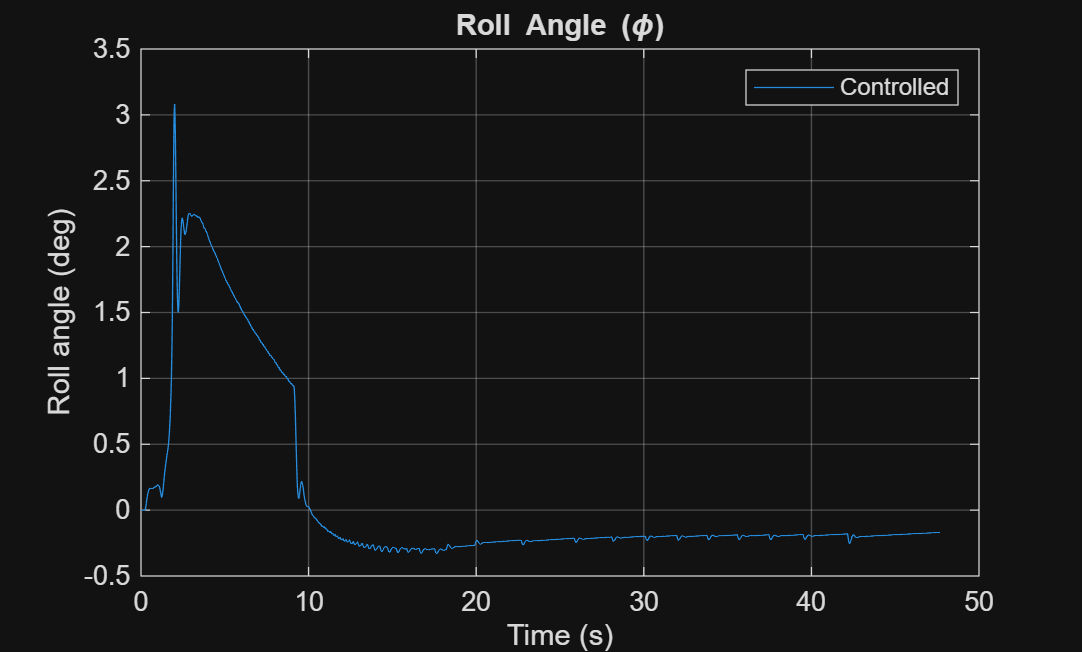


figure('Name','Roll Angle');
plot(t, rad2deg(phi_ctrl)); grid on
ylabel('Roll angle (deg)'); xlabel('Time (s)')
legend('Controlled')
title('Roll Angle (\phi)')